Data 

x = [3.0 4.5 7.0 9.0];
y = [2.5 1.0 2.5 0.5];

plot(x,y,'ko')
hold on

Quadratic spline

xx = 3 : 0.1 : 9

xx =     3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000    5.0000    5.1000    5.2000    5.3000    5.4000    5.5000    5.6000    5.7000    5.8000    5.9000    6.0000    6.1000    6.2000    6.3000    6.4000    6.5000    6.6000    6.7000    6.8000    6.9000    7.0000    7.1000    7.2000    7.3000    7.4000    7.5000    7.6000    7.7000    7.8000    7.9000


yy = quspline(x,y,xx)

yy =     2.5000    2.4000    2.3000    2.2000    2.1000    2.0000    1.9000    1.8000    1.7000    1.6000    1.5000    1.4000    1.3000    1.2000    1.1000    1.0000    0.9064    0.8256    0.7576    0.7024    0.6600    0.6304    0.6136    0.6096    0.6184    0.6400    0.6744    0.7216    0.7816    0.8544    0.9400    1.0384    1.1496    1.2736    1.4104    1.5600    1.7224    1.8976    2.0856    2.2864    2.5000    2.7040    2.8760    3.0160    3.1240    3.2000    3.2440    3.2560    3.2360    3.1840


p = spline(x,y)

p = struct with fields:
      form: 'pp'
    breaks: [3 4.5000 7 9]
     coefs: [3×4 double]
    pieces: 3
     order: 4
       dim: 1


yy_cubic =     2.5000    2.2752    2.0716    1.8883    1.7245    1.5796    1.4528    1.3433    1.2503    1.1732    1.1111    1.0633    1.0291    1.0076    0.9982    1.0000    1.0124    1.0345    1.0656    1.1050    1.1519    1.2055    1.2651    1.3299    1.3992    1.4722    1.5482    1.6264    1.7060    1.7864    1.8667    1.9461    2.0240    2.0996    2.1721    2.2407    2.3048    2.3635    2.4161    2.4619    2.5000    2.5298    2.5504    2.5612    2.5613    2.5500    2.5266    2.4903    2.4403    2.3759


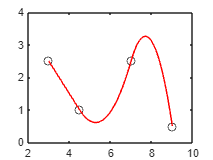


plot(x,y,'ko')
hold on

plot(xx,yy,'r-')
hold off
axis([2 10 0 4])